load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\'Prueba_Motor_0,2V' % para cargar el experimento a 0.2 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\'Prueba_Motor_0,2V_negativo' % para cargar el experimento a 0.2 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_1V % para cargar el experimento a 1 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_1V_negativo% para cargar el experimento a -1 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_2V % para cargar el experimento a 2 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_2V_negativo % para cargar el experimento a -2 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_4V % para cargar el experimento a 4 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_4V_Negativo% para cargar el experimento a -4 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_5V % para cargar el experimento a 5 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_5V_negativo% para cargar el experimento a -5 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_6V % para cargar el experimento a 6 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_6V_negativo% para cargar el experimento a -6 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_8V % para cargar el experimento a 8 V
load 'Archivos de Pruebas al motor'\'Ganancia 1_sin_carga'\Prueba_Motor_8V_negativo% para cargar el experimento a -8 V


Pruebas con el archivo de 0.2V(Señal minima para el funcionamiento del motor)

tiempo = Prueba_Motor_0_2V(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_0_2V(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_0_2V(:,3); % vector columna de valores de la salida
ts_acumulado=0;
gain_acumulado=0;
cnt=0;

Graficas de entrada salida de inicio:

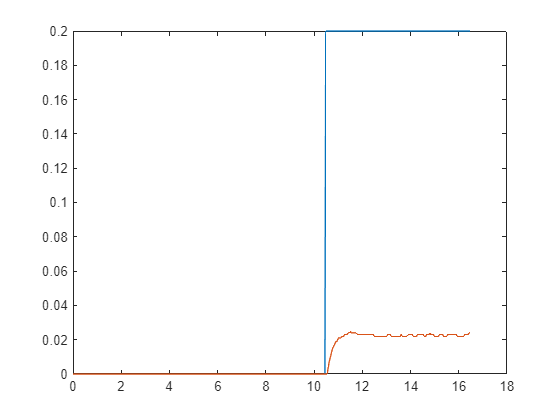

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

%valor_final = mean(salida(x_fin-10: x_fin-1))
%gain= valor_final/entrada(x_fin)
%gain_acumulado = gain_acumulado+ gain;
%ts=tiempo(find(salida>=(0.95*valor_final),1))-t_ini
%cnt=1;
%ts_acumulado= (ts_acumulado+ts);


Figura con los datos de interes:

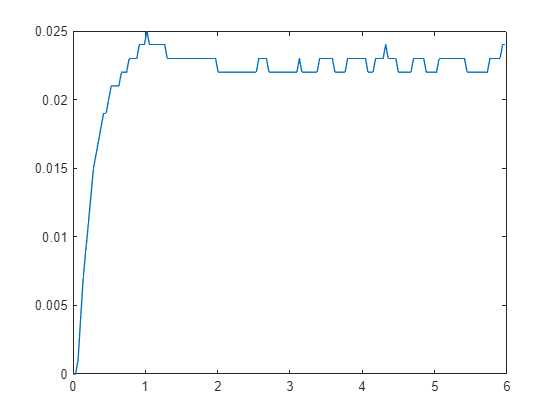

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

_______________________________________________________________________________________________________________________

Pruebas con el archivo de -0.2V(Señal minima para el funcionamiento del motor pero de manera inversa)

tiempo = Prueba_Motor_0_2V_negativo(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_0_2V_negativo(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_0_2V_negativo(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

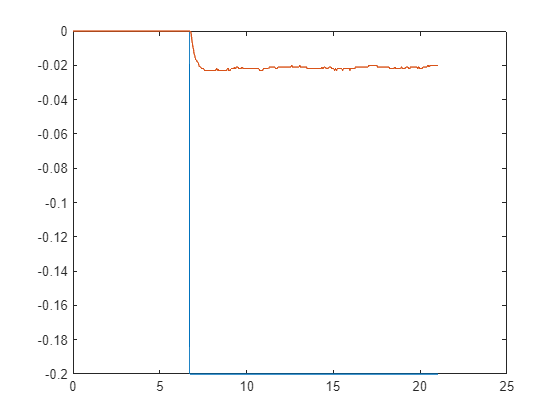

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

%Seleccion de la parte de interes de la grafica

Establecimiento de intervalos de interes:

t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

%valor_final = mean(salida(x_fin-10: x_fin-1))
%gain= valor_final/entrada(x_fin)
%gain_acumulado = gain_acumulado+ gain;
%ts=tiempo(find(salida<=(0.95*valor_final),1))-t_ini
%cnt=cnt+1;
%ts_acumulado= (ts_acumulado+ts);

Figura con los datos de interes:

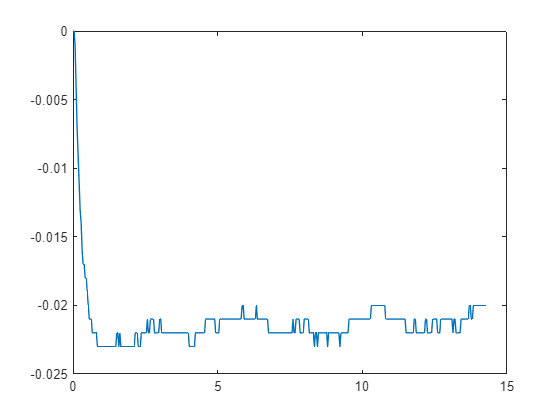

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de 1V

tiempo = Prueba_Motor_1V(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_1V(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_1V(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

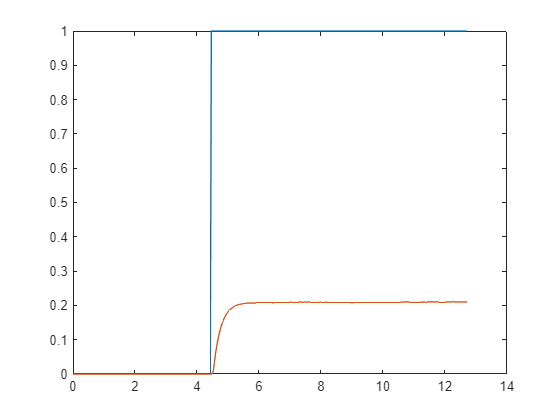

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final = mean(salida(x_fin-10: x_fin-1))

valor_final = 0.2100

gain= valor_final/entrada(x_fin)

gain = 0.2100

gain_acumulado = gain_acumulado+ gain;
ts=tiempo(find(salida>=(0.95*valor_final),1))-t_ini

ts = 0.8100

cnt=cnt+1;
ts_acumulado= (ts_acumulado+ts);

Figura con los datos de interes:

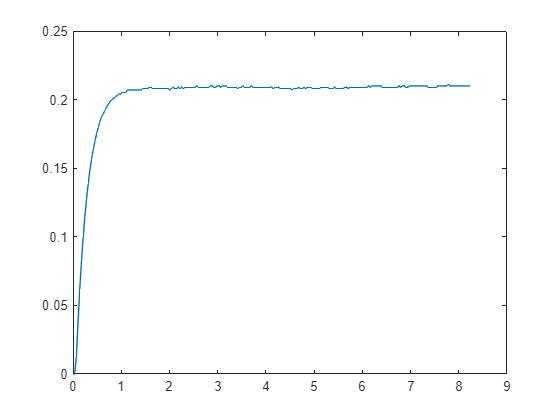

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de -2V

tiempo = Prueba_Motor_1V_negativo(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_1V_negativo(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_1V_negativo(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

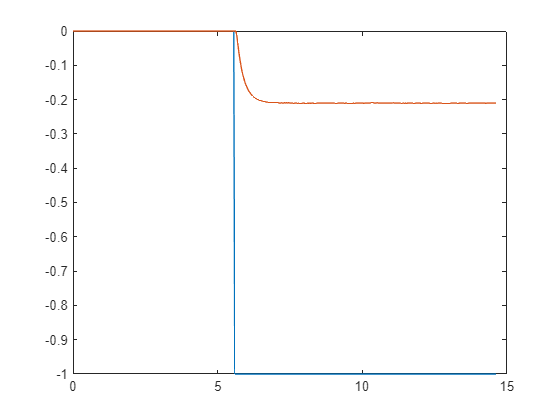

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final = mean(salida(x_fin-10: x_fin-1))

valor_final = -0.2101

gain= valor_final/entrada(x_fin)

gain = 0.2101

gain_acumulado = gain_acumulado+ gain;
ts=tiempo(find(salida<=(0.95*valor_final),1))-t_ini

ts = 0.8070

cnt=cnt+1;
ts_acumulado= (ts_acumulado+ts);


Figura con los datos de interes:

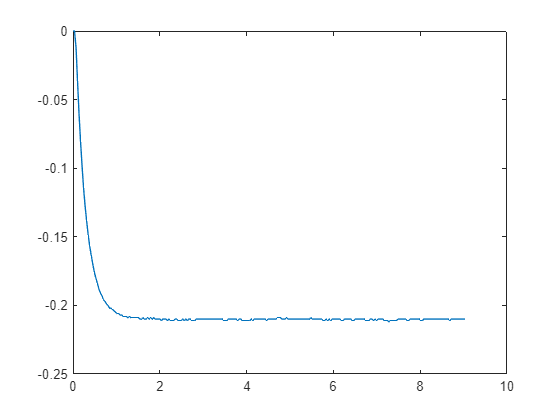

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de 2V

tiempo = Prueba_Motor_2V(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_2V(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_2V(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

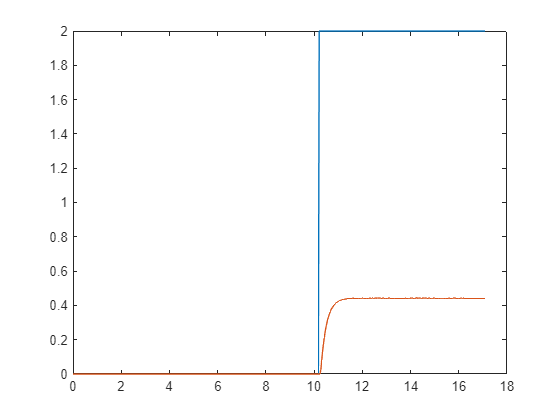

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final = mean(salida(x_fin-10: x_fin-1))

valor_final = 0.4401

gain= valor_final/entrada(x_fin)

gain = 0.2200

gain_acumulado = gain_acumulado+ gain;
ts=tiempo(find(salida>=(0.95*valor_final),1))-t_ini

ts = 0.7400

cnt=cnt+1;
ts_acumulado= (ts_acumulado+ts);


Figura con los datos de interes:

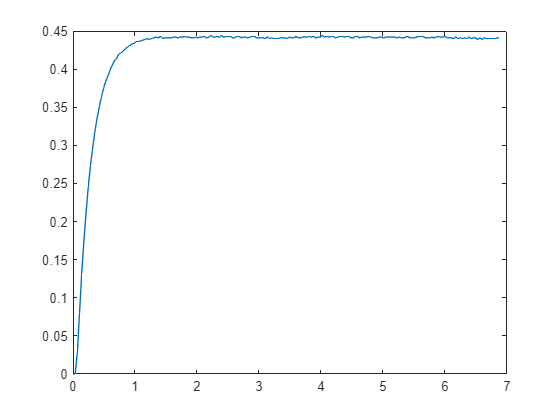

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de -2V

tiempo = Prueba_Motor_2V_negativo(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_2V_negativo(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_2V_negativo(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

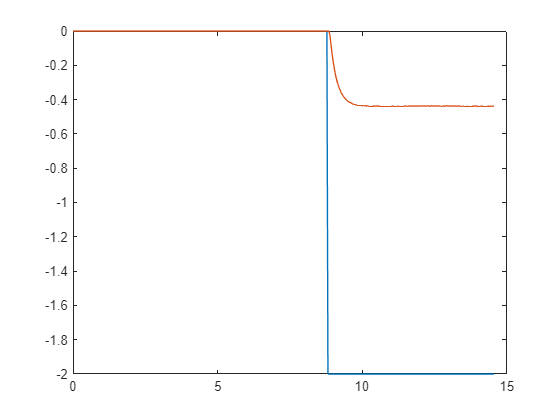

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final = mean(salida(x_fin-10: x_fin-1))

valor_final = -0.4390

gain= valor_final/entrada(x_fin)

gain = 0.2195

gain_acumulado = gain_acumulado+ gain;
ts=tiempo(find(salida<=(0.95*valor_final),1))-t_ini

ts = 0.8090

cnt=cnt+1;
ts_acumulado= (ts_acumulado+ts);


Figura con los datos de interes:

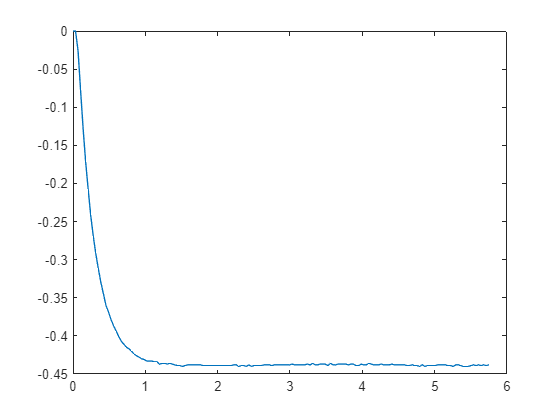

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de 4V

tiempo = Prueba_Motor_4V(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_4V(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_4V(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

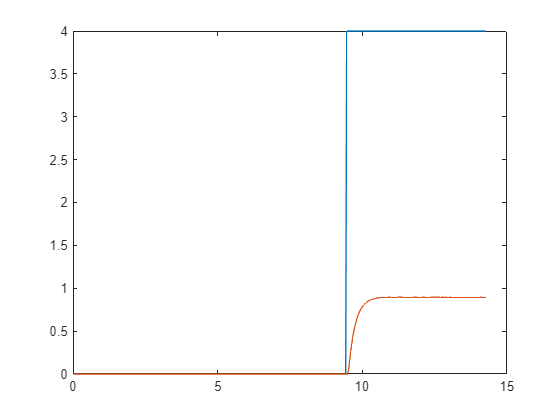

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final = mean(salida(x_fin-10: x_fin-1))

valor_final = 0.8932

gain= valor_final/entrada(x_fin)

gain = 0.2233

gain_acumulado = gain_acumulado+ gain;
ts=tiempo(find(salida>=(0.95*valor_final),1))-t_ini

ts = 0.7380

cnt=cnt+1;
ts_acumulado= (ts_acumulado+ts);


Figura con los datos de interes:

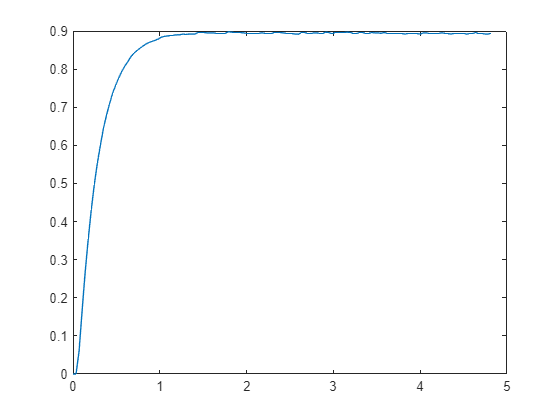

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de -4V

tiempo = Prueba_Motor_4V_Negativo(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_4V_Negativo(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_4V_Negativo(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

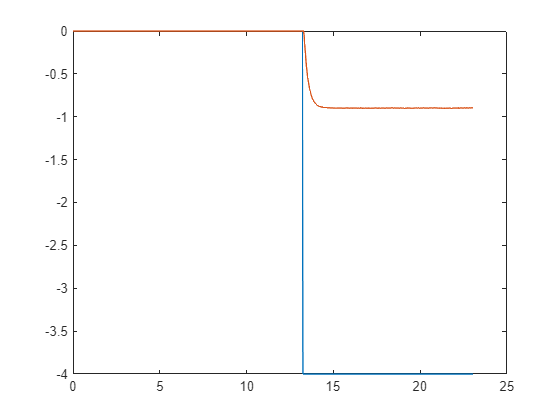

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final = mean(salida(x_fin-10: x_fin-1))

valor_final = -0.8966

gain= valor_final/entrada(x_fin)

gain = 0.2242

gain_acumulado = gain_acumulado+ gain;
ts=tiempo(find(salida<=(0.95*valor_final),1))-t_ini

ts = 0.7750

cnt=cnt+1;
ts_acumulado= (ts_acumulado+ts);

Figura con los datos de interes:

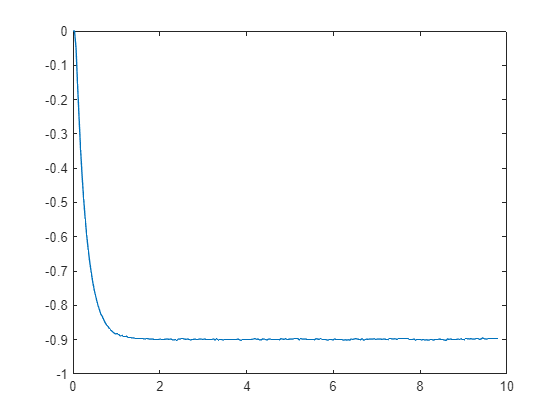

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de 5V

tiempo = Prueba_Motor_5V(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_5V(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_5V(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

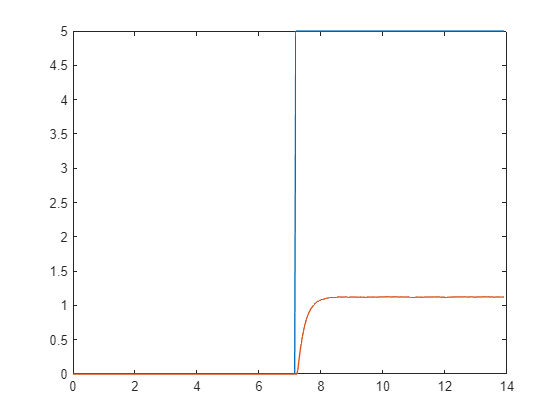

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final = mean(salida(x_fin-10: x_fin-1))

valor_final = 1.1219

gain= valor_final/entrada(x_fin)

gain = 0.2244

gain_acumulado = gain_acumulado+ gain;
ts=tiempo(find(salida>=(0.95*valor_final),1))-t_ini

ts = 0.7720

cnt=cnt+1;
ts_acumulado= (ts_acumulado+ts);

Figura con los datos de interes:

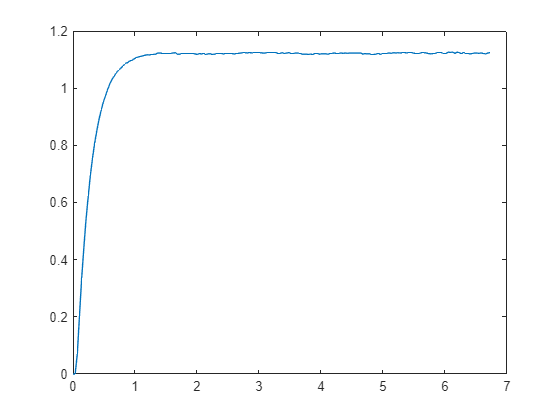

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de -5V

tiempo = Prueba_Motor_5V_negativo(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_5V_negativo(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_5V_negativo(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

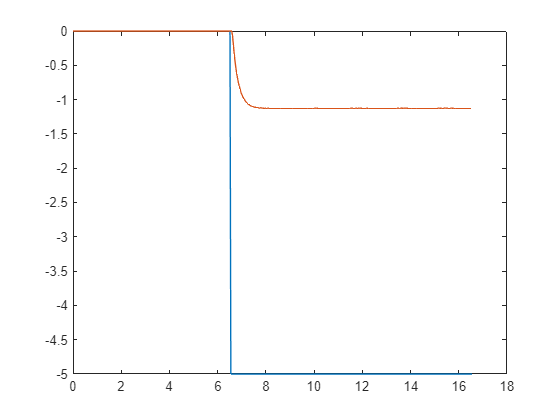

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final = mean(salida(x_fin-10: x_fin-1))

valor_final = -1.1287

gain= valor_final/entrada(x_fin)

gain = 0.2257

gain_acumulado = gain_acumulado+ gain;
ts=tiempo(find(salida<=(0.95*valor_final),1))-t_ini

ts = 0.7750

cnt=cnt+1;
ts_acumulado= (ts_acumulado+ts);

Figura con los datos de interes:

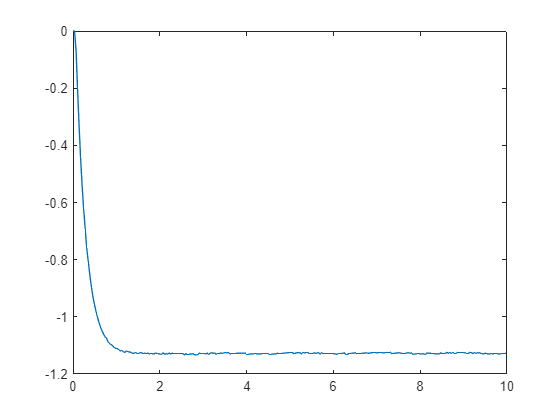

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de 6V

tiempo = Prueba_Motor_6V(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_6V(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_6V(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

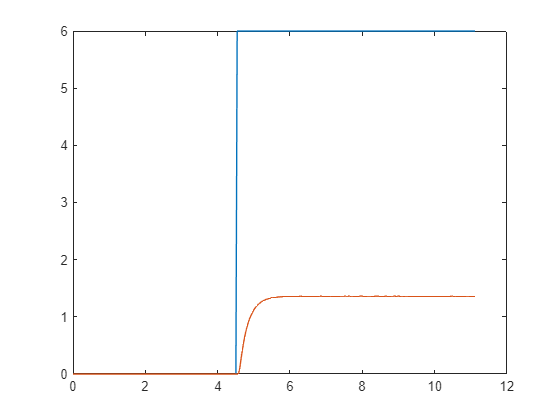

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final = mean(salida(x_fin-10: x_fin-1))

valor_final = 1.3581

gain= valor_final/entrada(x_fin)

gain = 0.2263

gain_acumulado = gain_acumulado+ gain;
ts=tiempo(find(salida>=(0.95*valor_final),1))-t_ini

ts = 0.7730

cnt=cnt+1;
ts_acumulado= (ts_acumulado+ts);

Figura con los datos de interes:

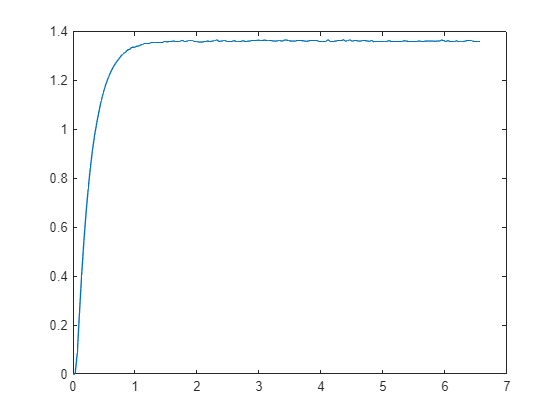

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de -6V

tiempo = Prueba_Motor_6V_negativo(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_6V_negativo(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_6V_negativo(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

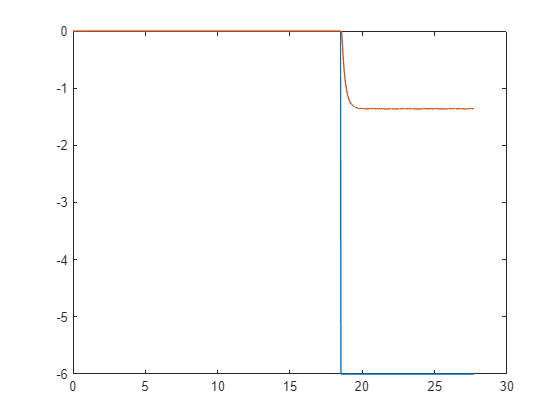

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final = mean(salida(x_fin-10: x_fin-1))

valor_final = -1.3599

gain= valor_final/entrada(x_fin)

gain = 0.2267

gain_acumulado = gain_acumulado+ gain;
ts=tiempo(find(salida<=(0.95*valor_final),1))-t_ini

ts = 0.7740

cnt=cnt+1;
ts_acumulado= (ts_acumulado+ts);

Figura con los datos de interes:

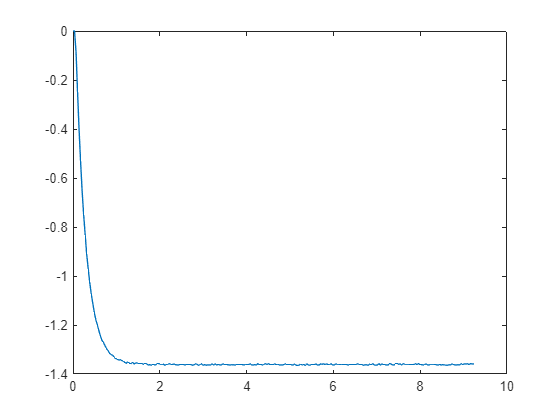

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de 8V

tiempo = Prueba_Motor_8V(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_8V(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_8V(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

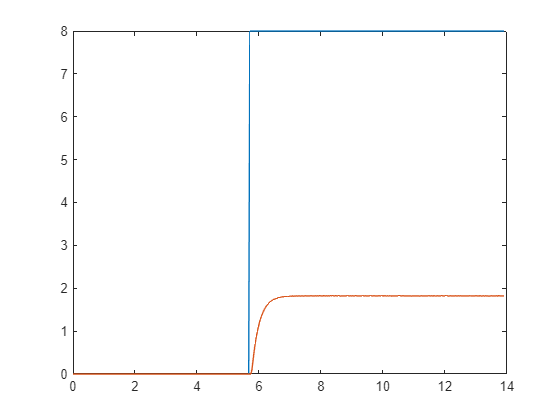

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final = mean(salida(x_fin-10: x_fin-1))

valor_final = 1.8216

gain= valor_final/entrada(x_fin)

gain = 0.2277

gain_acumulado = gain_acumulado+ gain;
ts=tiempo(find(salida>=(0.95*valor_final),1))-t_ini

ts = 0.7750

cnt=cnt+1;
ts_acumulado= (ts_acumulado+ts);


Figura con los datos de interes:

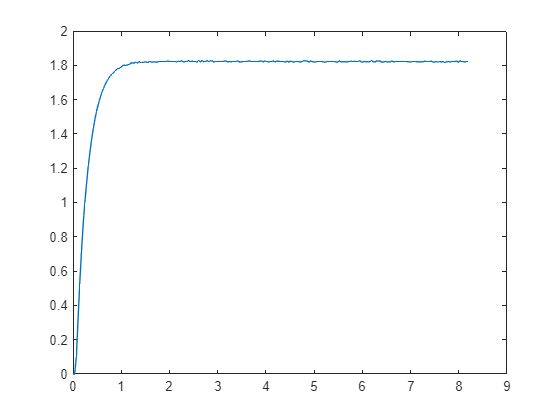

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y

________________________________________________________________________________________________________________________

Pruebas con el archivo de -8V

tiempo = Prueba_Motor_8V_negativo(:,1); % vector columna de valores del tiempo
entrada = Prueba_Motor_8V_negativo(:,2); % vector columna de valores de la entrada
salida = Prueba_Motor_8V_negativo(:,3); % vector columna de valores de la salida

Graficas de entrada salida de inicio:

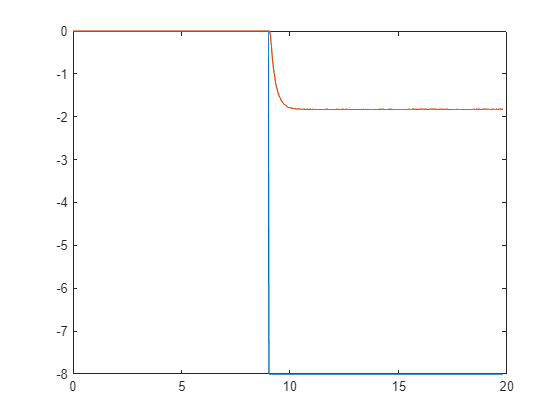

figure
plot(tiempo,entrada) % representación gráfica X,Y
hold on % para superponer la(s) siguiente(s) curva(s)
plot(tiempo,salida) % representación gráfica X,Y

Establecimiento de intervalos de interes:

%Seleccion de la parte de interes de la grafica
t_ini = tiempo(find(entrada ~= 0, 1));  % `1` indica que solo queremos el primer valor que cumpla la condición
t_fin= tiempo(numel(entrada));
x_ini = find(tiempo==t_ini); % nº de muestra del punto inicial
x_fin = find(tiempo==t_fin); % nº de muestra del punto final

Valores de interes para la funcion de transferencia de la planta:

valor_final = mean(salida(x_fin-10: x_fin-1))

valor_final = -1.8231

gain= valor_final/entrada(x_fin)

gain = 0.2279

gain_acumulado = gain_acumulado+ gain;
ts=tiempo(find(salida<=(0.95*valor_final),1))-t_ini

ts = 0.7730

cnt=cnt+1;
ts_acumulado= (ts_acumulado+ts);

Figura con los datos de interes:

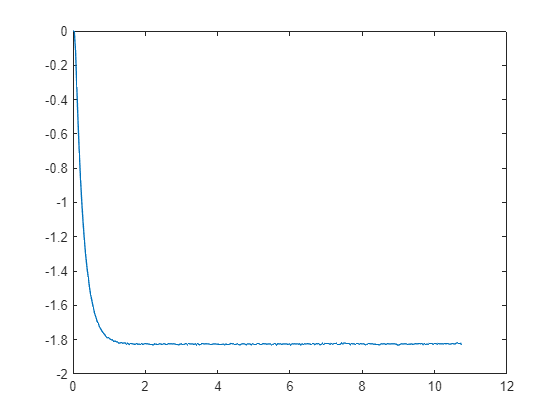

tiempo_interes = tiempo(x_ini:x_fin)-tiempo(x_ini); % delimitación del tiempo y origen en t=0
salida_interes = salida(x_ini:x_fin); % delimitación de la salida
figure % nueva ventana gráfica
plot(tiempo_interes,salida_interes) % representación gráfica X,Y


media_ts=ts_acumulado/cnt

media_ts = 0.7767

media_gain=gain_acumulado/cnt

media_gain = 0.2222

De estos datos sacamos que la G(S) de nuestro sistema =

N= [media_gain]

N = 0.2222

D= [media_ts 1]

D =     0.7767    1.0000


G=tf(N,D)


G =
 
     0.2222
  ------------
  0.7767 s + 1
 
Continuous-time transfer function.
Model Properties


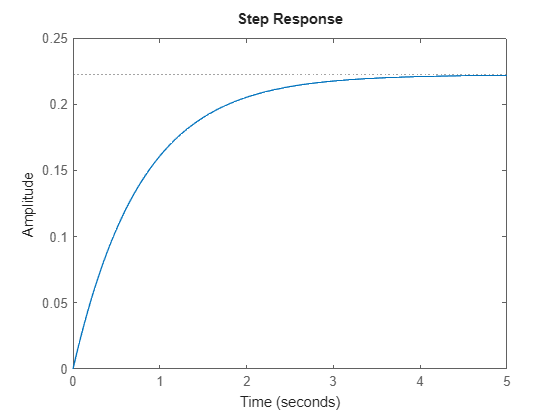

stepplot(g)

Forma normalizada

N= [media_gain/media_ts]

N = 0.2860

D= [1 1/media_ts]

D =     1.0000    1.2874


G=tf(N,D)


G =
 
    0.286
  ---------
  s + 1.287
 
Continuous-time transfer function.
Model Properties


stepplot(g)